# Join Tables Using Live Editor Task

This example shows how to use the **Join Tables** Live Editor task to perform an inner join and an outer join on two tables.

First, load the `orders` table, which has order IDs, customer names, and the order date for a number of shipments.

load orders

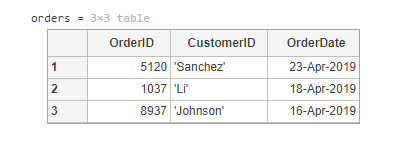

Then load the `items` table, which contains products that customers ordered, along with the price and status of the shipment for that item. Each row of this table has an order ID, just like `orders`. Because a customer can order multiple items, several rows of `items` can refer to one order from `orders`.

load items

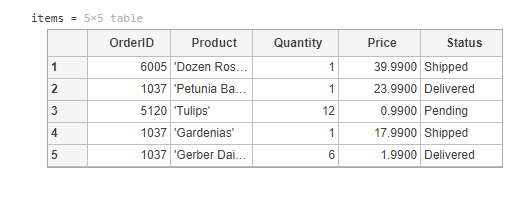

Open the **Join Tables** task. To open the task, type the keyword `join` in a code block and click `Join Tables` when it appears in the menu.

Use the task to perform an *inner join* of `orders` and `items`. When the task opens:

- Select `orders` and `items` as the left and right tables, respectively.

- Select `OrderID` as the merging variable for both tables.

- Click the **Inner join** button.

- To see the code that this task generates, click the small arrow under the **Display results** section. In this example, the generated code is a call to the `innerjoin` function.

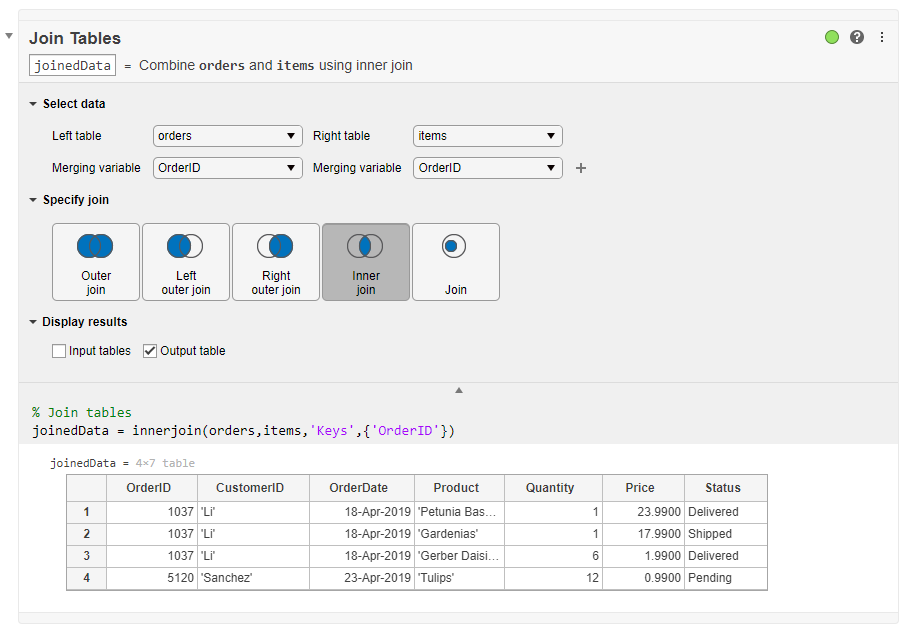

When you perform an inner join, the output table includes only those key values that appear in *both* the left and right tables.

- Only the values `1037` and `5120` occur in both input tables. Therefore, the output table contains data for only those two orders.

- Value `1037` occurs multiple times in `items`, once for each item, but only once in `orders`. Therefore, the `CustomerID` and `OrderDate` values corresponding to `1037` are copied as many times as needed in the output.

Next, use the task to perform a *left outer join*. Outer joins can include key values that appear in only one input table. For example, a left outer join includes all key values from the left table, even when the right table has no corresponding matches. If the right table has key values that do not have matches in the left table, then those key values are not included. 

- Click the **Left outer join** button.

- Select the **Combine merging variables** check box. By default, outer joins copy the key variables from the left and right tables into separate variables in the output table. Merge the key variables so one key variable is in the output.

- To see the generated call to the `outerjoin` function, click the small arrow under **Display results**.

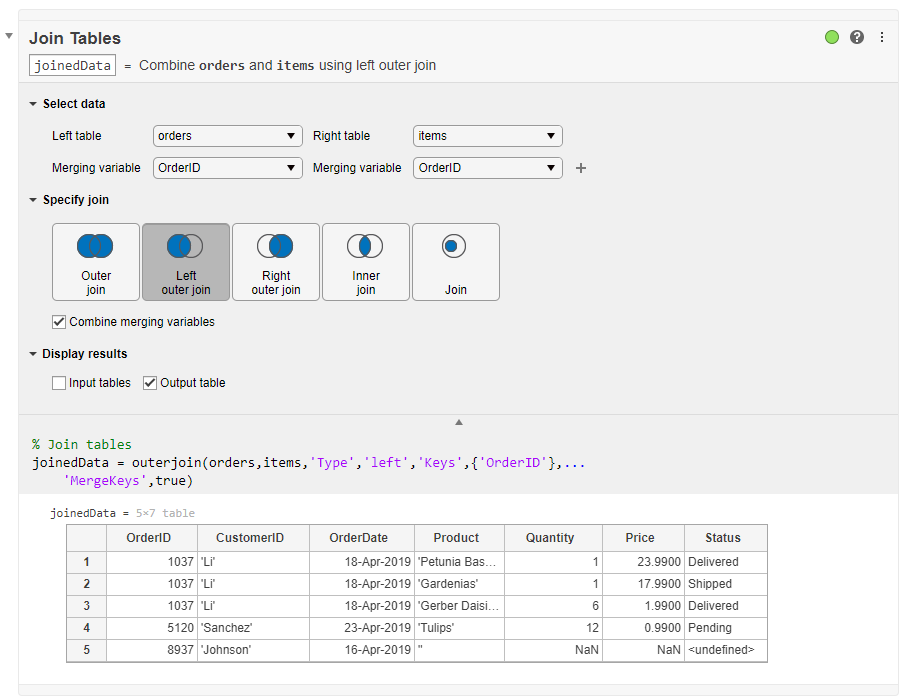

The output table now includes data for order `8937`. However, because the `items` table for order `8937` had no items, the rest of the row is filled in with empty values (such as `''`, `NaN`, or `<undefined>`). Outer joins fill table elements with empty values when the left or right tables do not have data associated with a key value.

- Full outer joins include all key values and data from both tables.

- Left outer joins include all key values and data from the left table, but only matching key values and associated data from the right.

- Right outer joins include all key values and data from the right table, but only matching key values and associated data from the left.

*Copyright 2019-2020 The MathWorks, Inc.*